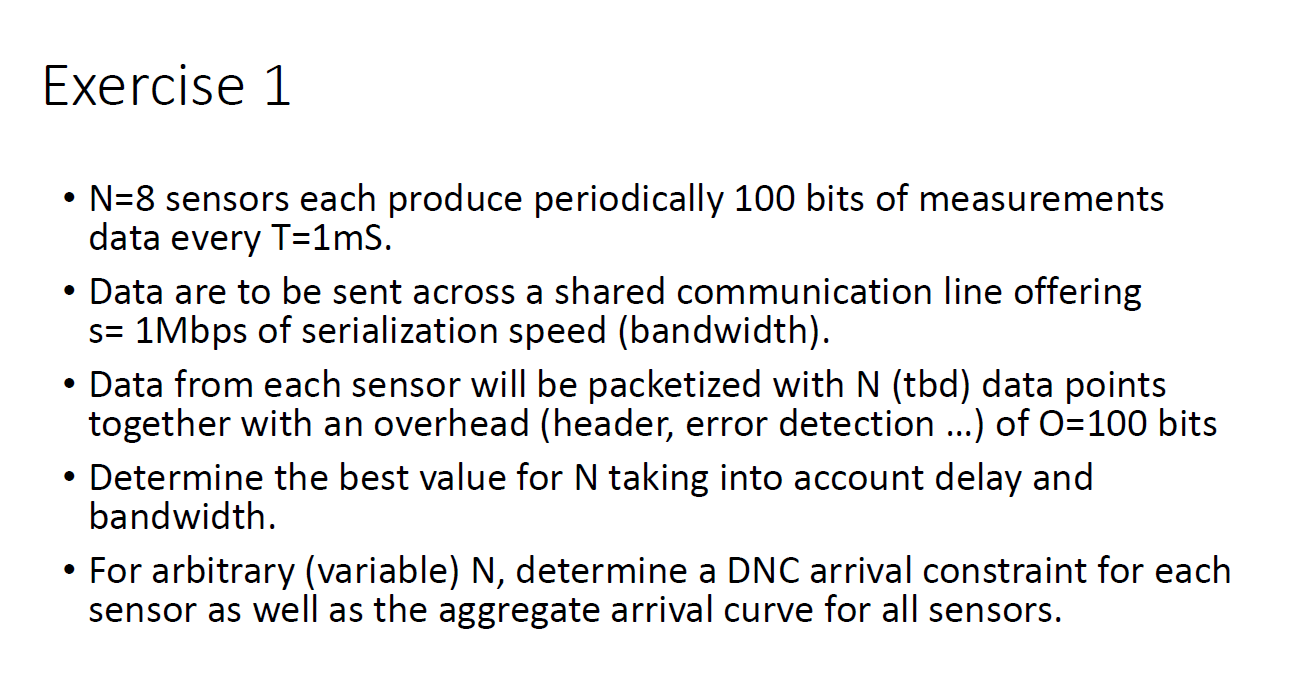

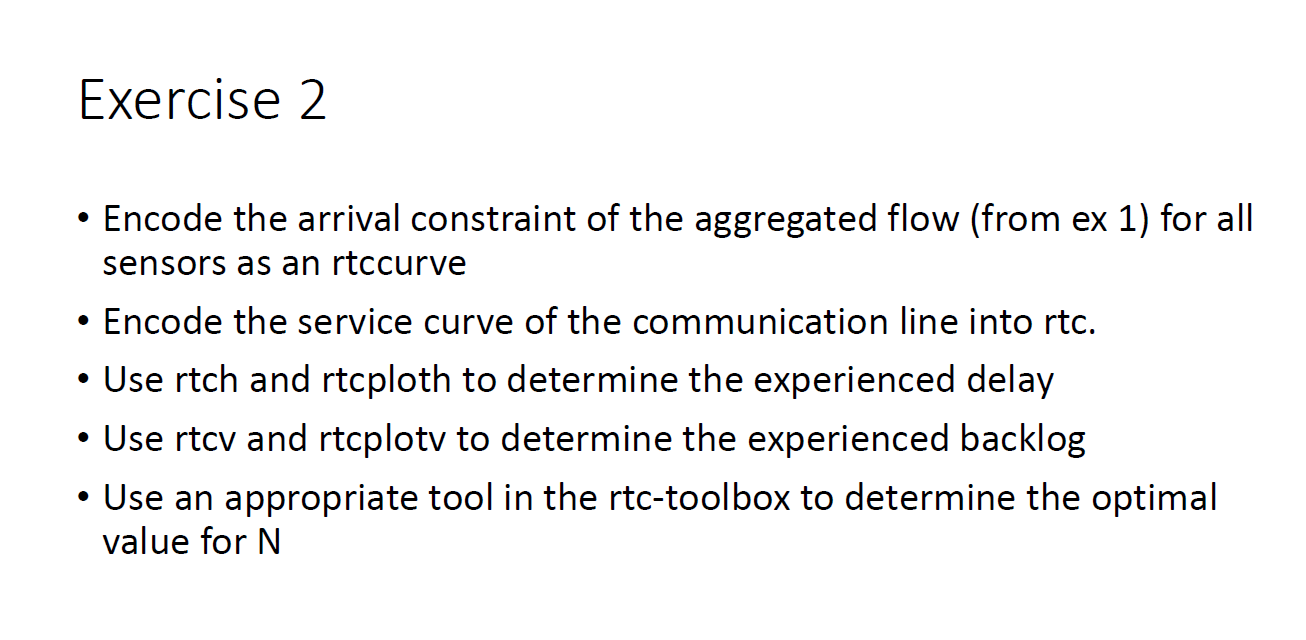

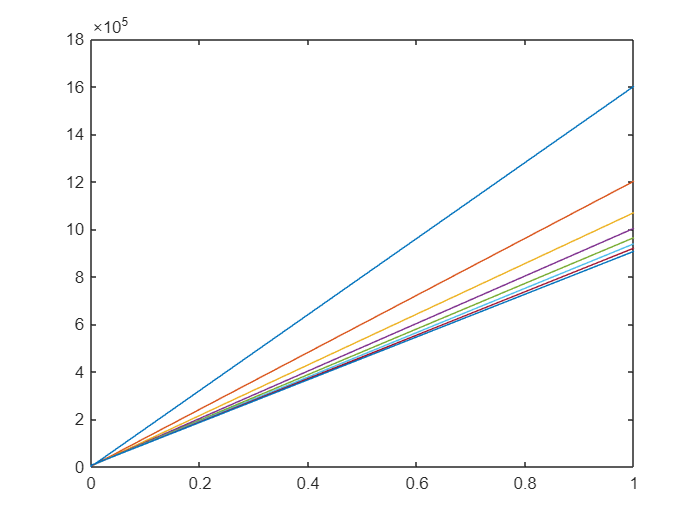

for N = 1:8
    r = 8*(100000 + 100000/N);
    burst = 8*(100*N + 100);

    alpha{N} = rtccurve([0,burst,r]);
end
rtcplot(alpha{:})

N = 5;

r = 8*(100000 + 100000/N);
b = 8*(100*N + 100)

b = 4800


a = rtccurve([0,b,r]);
noBurst = rtccurve([0,0,r]);
beta = rtccurve([0,0,1e6]); %ServiceCurve

rtcplot(a, noBurst, beta)


D = rtch(a,beta)

D = 0.0048

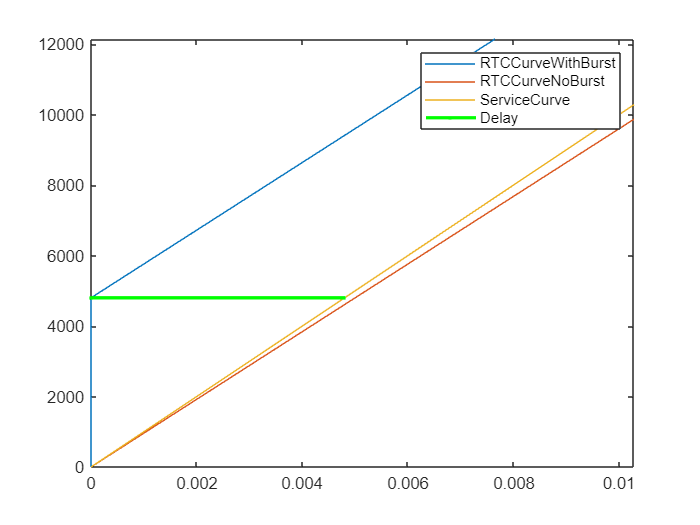


rtcploth(a,beta);

legend('RTCCurveWithBurst','RTCCurveNoBurst', 'ServiceCurve', 'Delay')
xlim([0.00000 0.01028])
ylim([0 12144])

B = rtcv(a,beta)

B = 4800

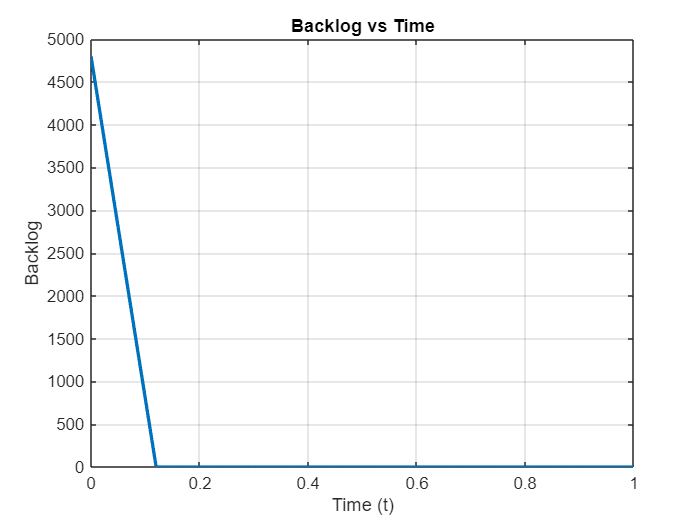

% Time vector
t = 0:0.001:1;  % t from 0 to 100

% Compute backlog
backlog = max(B + (r - 1e6) * t,0);

% Plot
plot(t, backlog, 'LineWidth', 2)
xlabel('Time (t)')
ylabel('Backlog')
title('Backlog vs Time')
grid on

beta = rtccurve([0,0,1e6]);

Nvals = 1:20;
delay = NaN(size(Nvals));

for N = Nvals

    r = 8*(100000 + 100000/N);
    b = 8*(100*N + 100);

    % skip infeasible solutions
    if r >= 1e6
        continue
    end

    alpha = rtccurve([0,b,r]);

    delay(N) = rtch(alpha,beta);

end

[minDelay,idx] = min(delay);

optimalN = Nvals(idx)

optimalN = 5

%Excercise 3

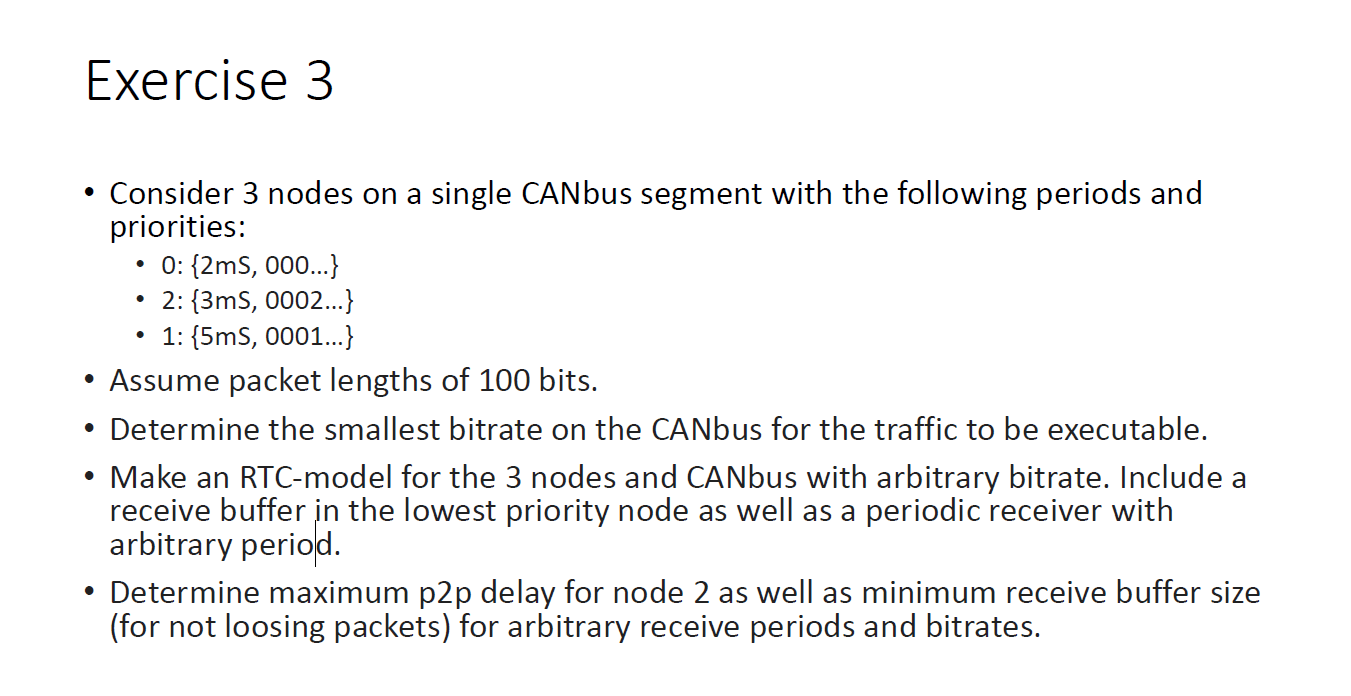

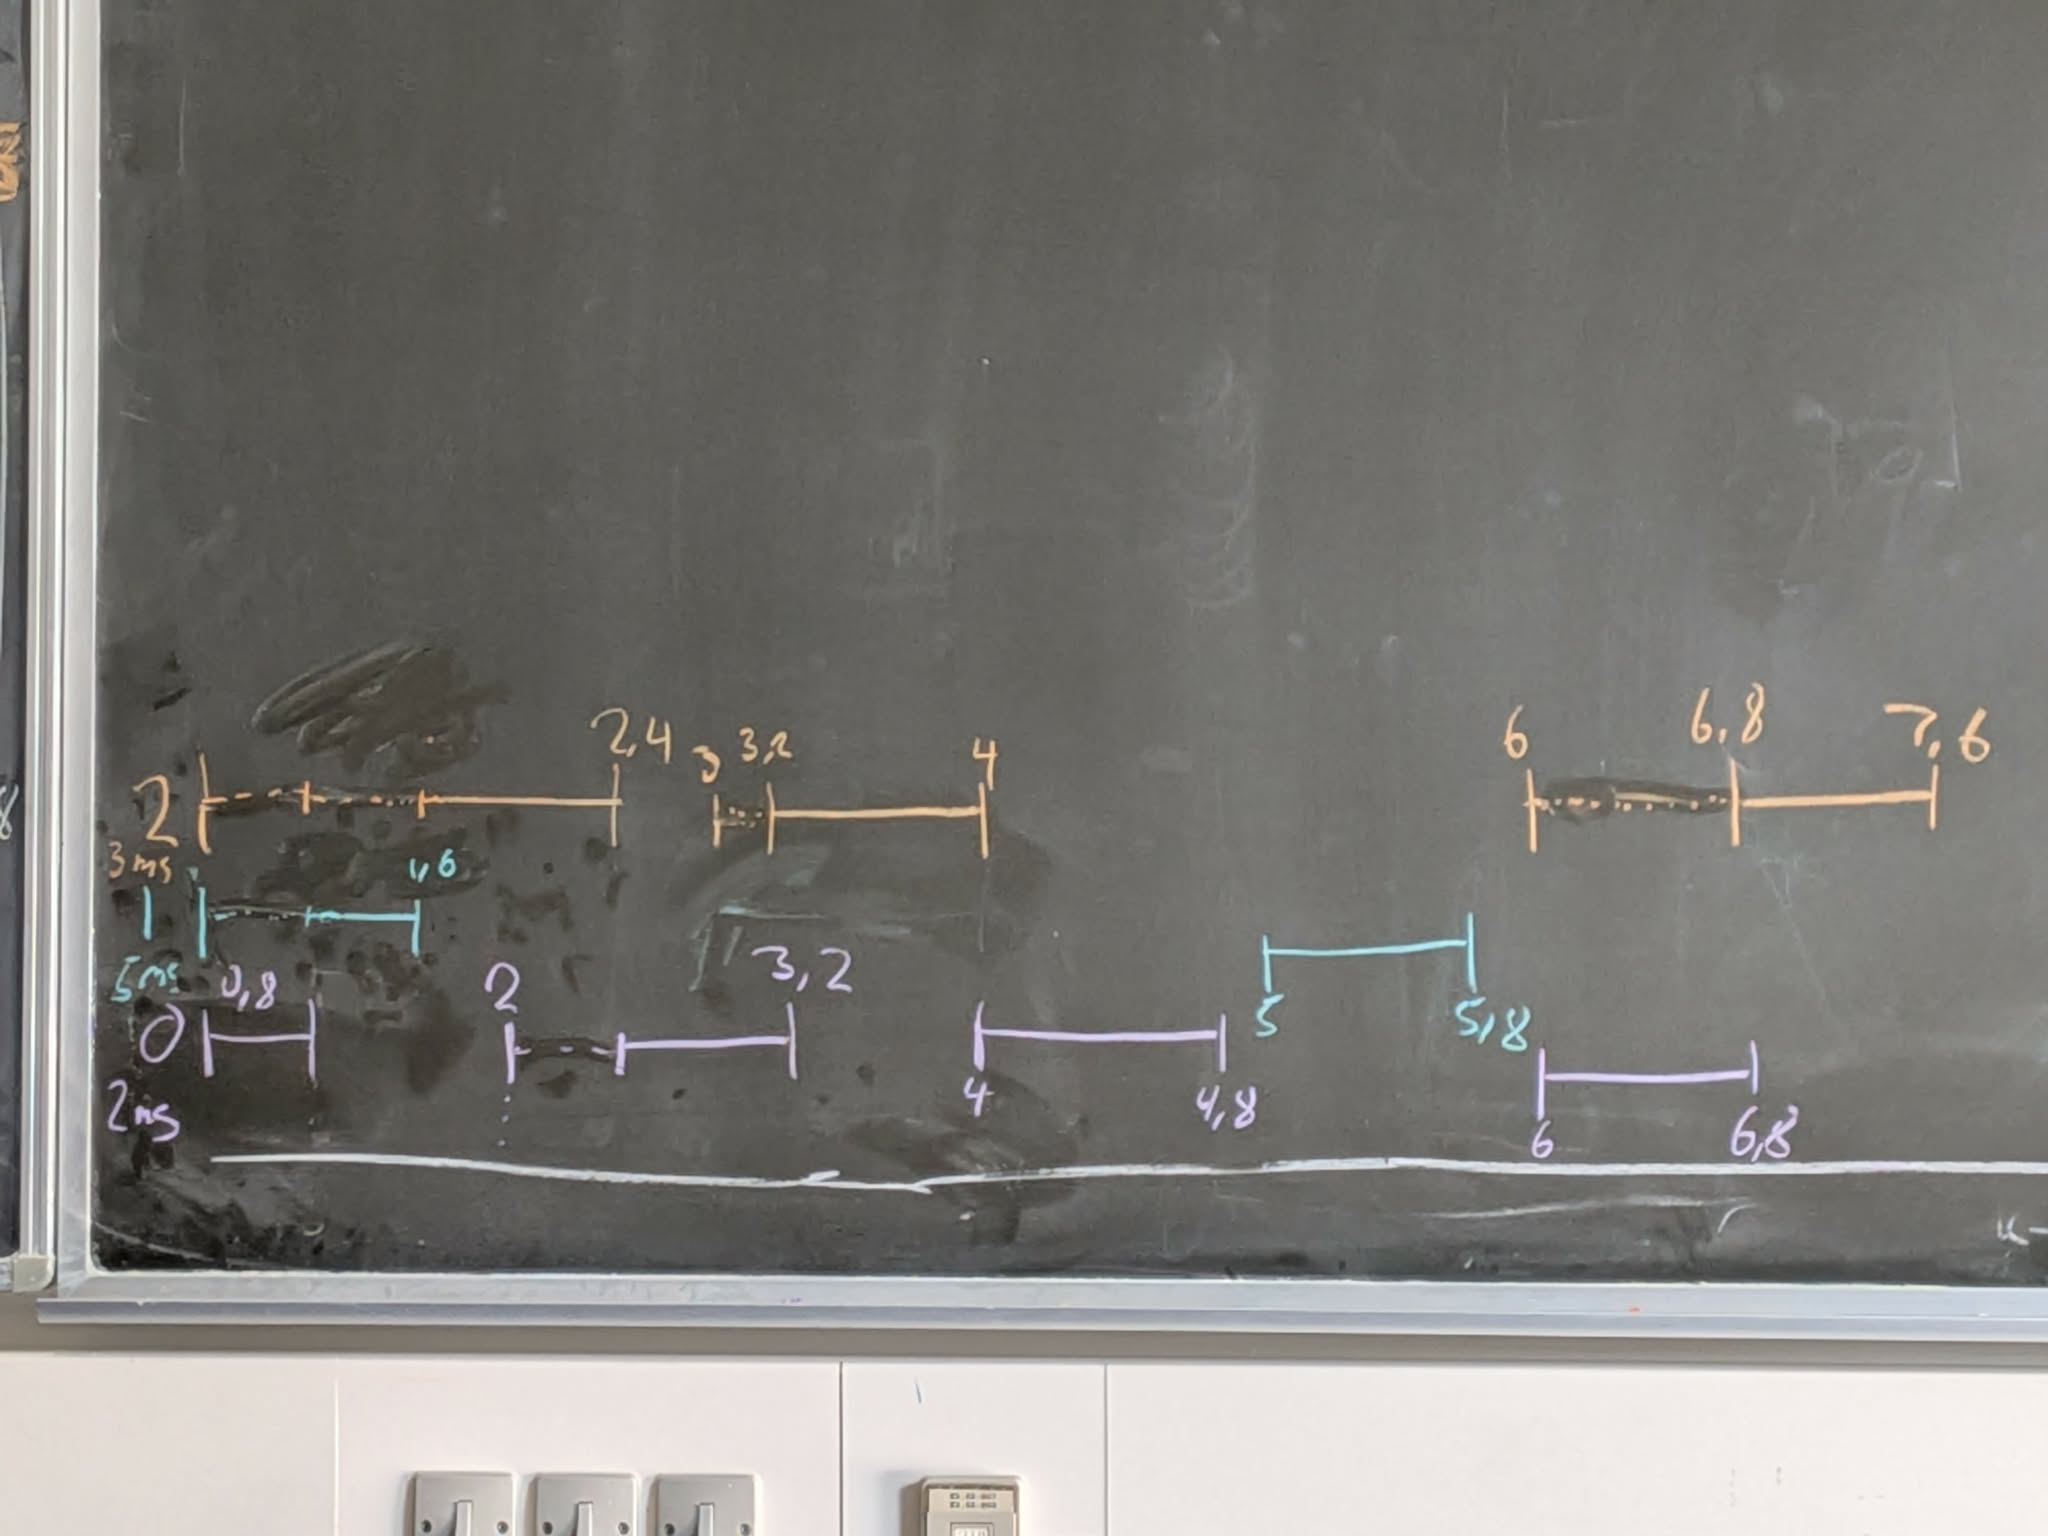

%% Traffic parameters

L  = 100;       % bits

T0 = 2e-3;
T1 = 5e-3;
T2 = 3e-3;

%% Minimum average bitrate

Bmin = L*(1/T0 + 1/T1 + 1/T2);

fprintf('Minimum bitrate = %.2f bit/s\n',Bmin);

Minimum bitrate = 103333.33 bit/s


fprintf('Minimum bitrate = %.2f kbit/s\n',Bmin/1000);

Minimum bitrate = 103.33 kbit/s


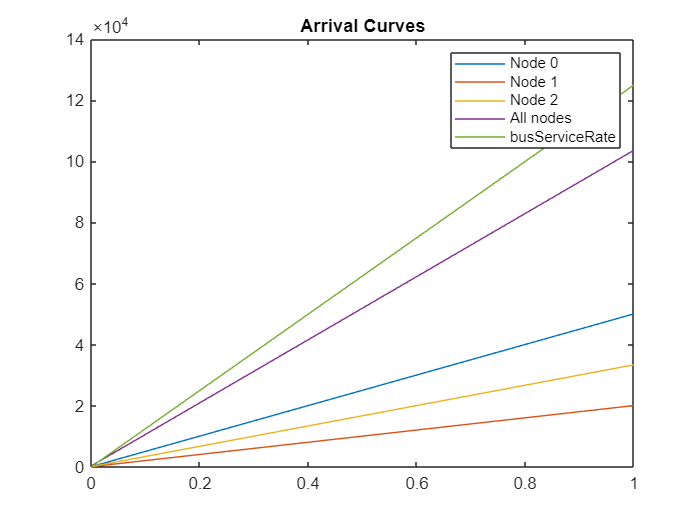

%% Arrival curves

L = 100;

a0 = rtccurve([0,L,L/0.002]);   % highest priority
a1 = rtccurve([0,L,L/0.005]);   % medium priority
a2 = rtccurve([0,L,L/0.003]);   % lowest priority
a3 = rtccurve([0,3*L,Bmin]);

%% CAN bitrate

B = 125e3;

betaBus = rtccurve([0,0,B]);
figure(1)

rtcplot(a0,a1,a2,a3, betaBus)

title('Arrival Curves')
legend('Node 0','Node 1','Node 2','All nodes', 'busServiceRate')

%% Delay bound

D2 = rtch(a2,betaBus);

fprintf('Node 2 bus delay = %.6f s\n',D2);

Node 2 bus delay = 0.000800 s


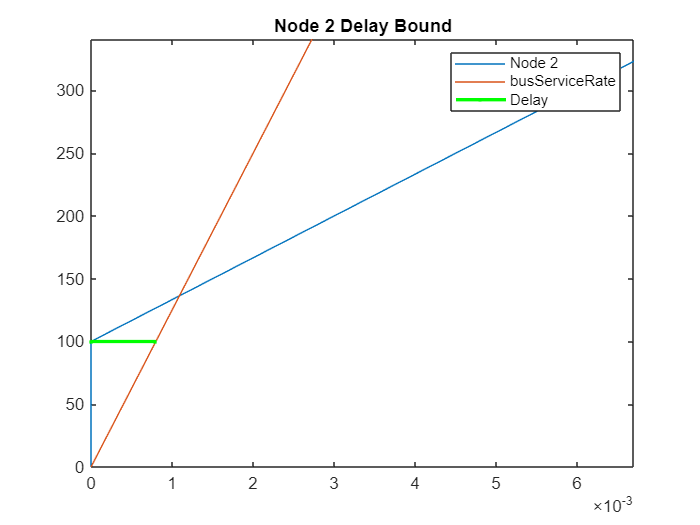

figure(3)
rtcplot(a2,betaBus)
rtcploth(a2,betaBus)

legend('Node 2', 'busServiceRate', 'Delay')
title('Node 2 Delay Bound')

xlim([0.00000 0.00670])
ylim([0 341])
zlim([-1.00 1.00])

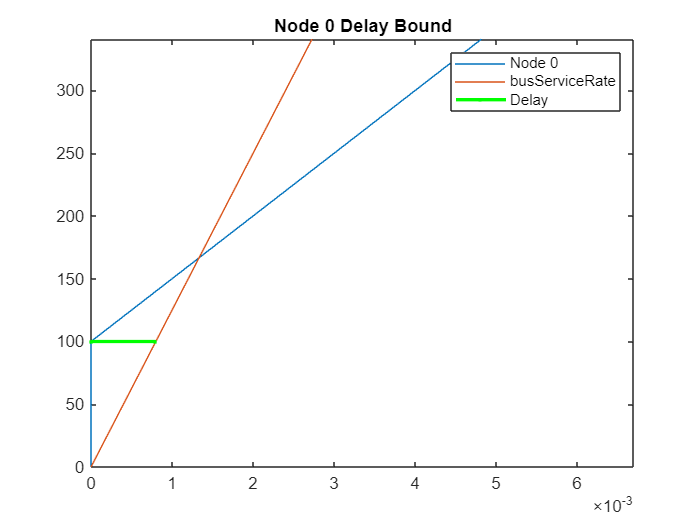

rtcplot(a0,betaBus)
rtcploth(a0,betaBus)

legend('Node 0', 'busServiceRate', 'Delay')
title('Node 0 Delay Bound')

xlim([0.00000 0.00670])
ylim([0 341])
zlim([-1.00 1.00])

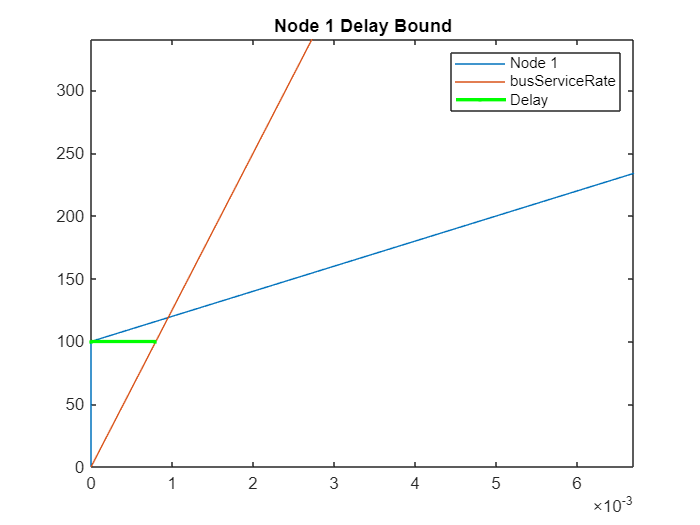


rtcplot(a1,betaBus)
rtcploth(a1,betaBus)

legend('Node 1', 'busServiceRate', 'Delay')
title('Node 1 Delay Bound')

xlim([0.00000 0.00670])
ylim([0 341])
zlim([-1.00 1.00])

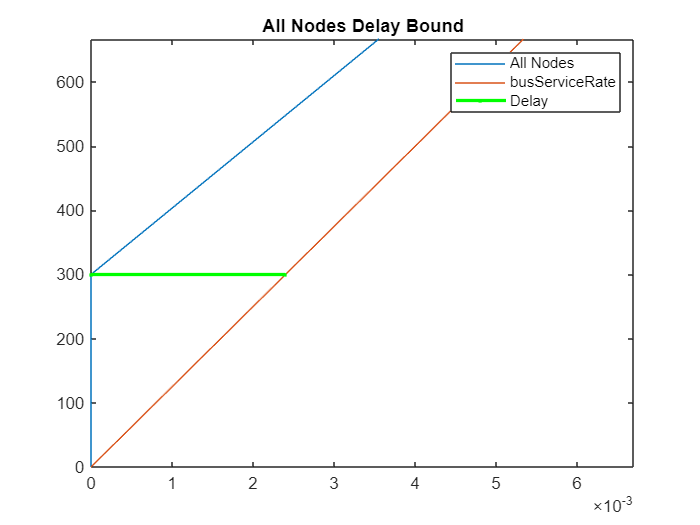


rtcplot(a3,betaBus)
rtcploth(a3,betaBus)

legend('All Nodes', 'busServiceRate', 'Delay')
title('All Nodes Delay Bound')

xlim([0.00000 0.00670])
ylim([0 341])
zlim([-1.00 1.00])

xlim([0.00000 0.00670])
ylim([0 667])
zlim([-1.00 1.00])


AvgRateN2 = L*(1/0.002+1/0.005)

AvgRateN2 = 70000

TB = 0.01;
maxBuffer = 2*L + TB*AvgRateN2

maxBuffer = 900